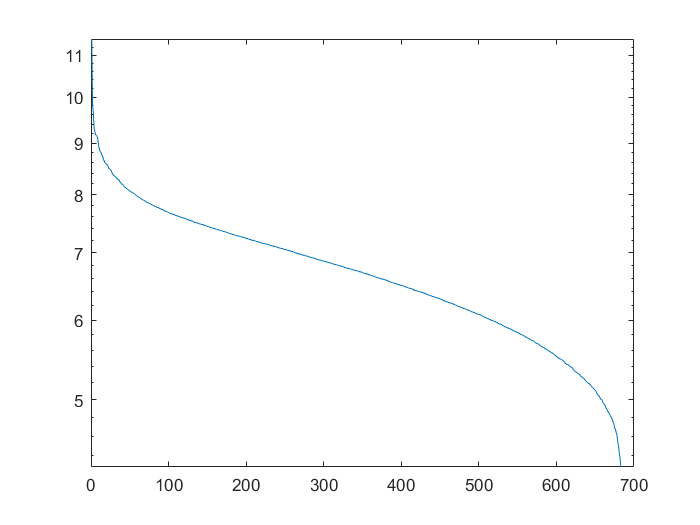

img=imread('../../img/Netherland.jpg');
% imshow(img)
red=double(img(:,:,1));
green=double(img(:,:,2));
blue=double(img(:,:,3));
[u1,s1,v1]=mysvd(red);
[u2,s2,v2]=mysvd(green);
[u3,s3,v3]=mysvd(blue);
y_red=(diag(s1(1:min(size(s1)),1:min(size(s1)))));
y_green=(diag(s2(1:min(size(s2)),1:min(size(s2)))));
y_blue=(diag(s3(1:min(size(s3)),1:min(size(s3)))));
% section semilogy
semilogy(1:length(y_red) , log(y_red))

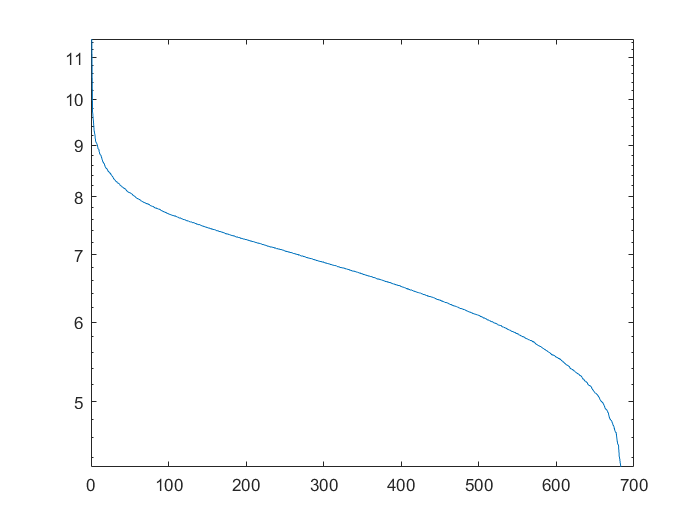

semilogy(1:length(y_green) , log(y_green))

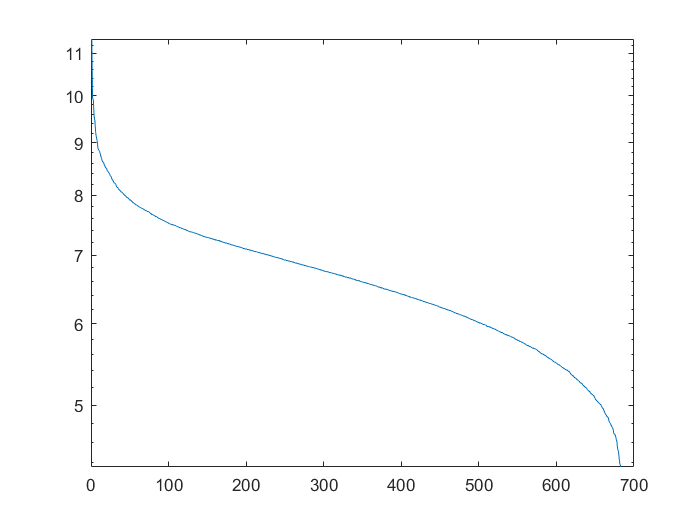

semilogy(1:length(y_blue) , log(y_blue))

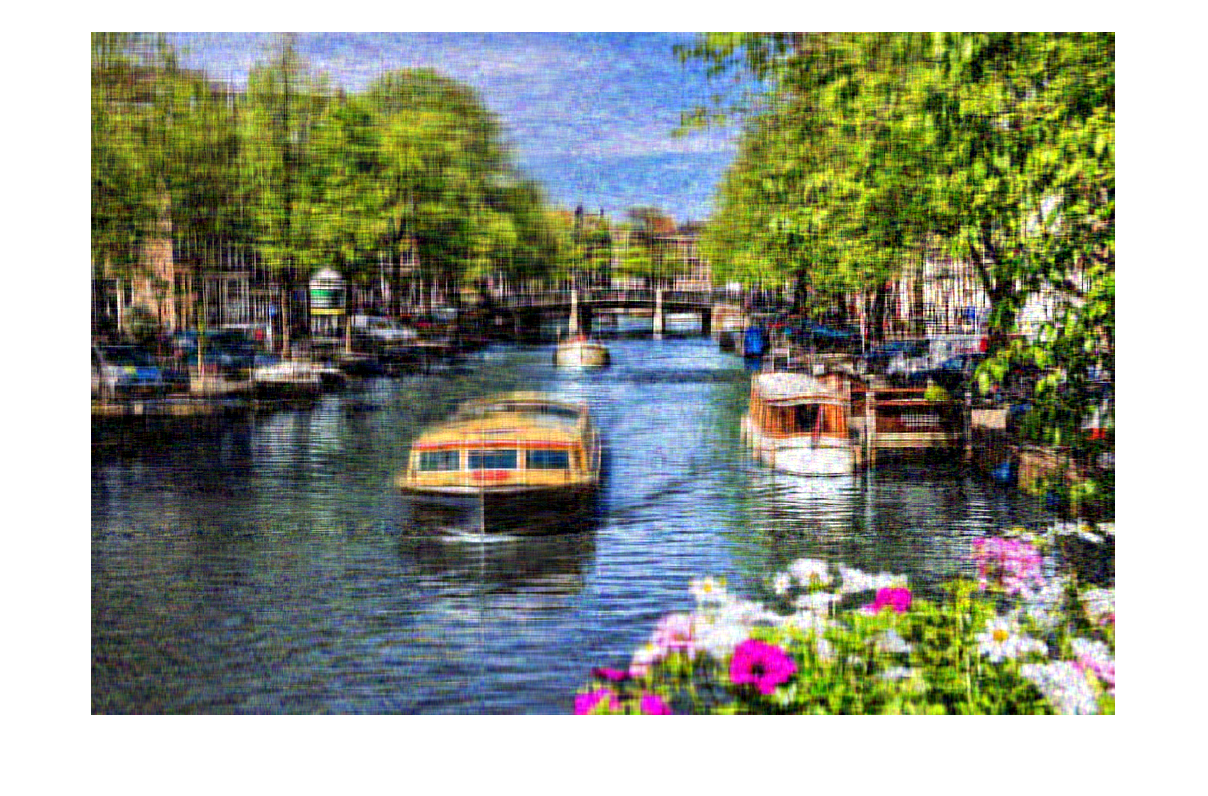

%---------------

% test with p=1
p=50;
new_img=zeros(size(img,1),size(img,2),3);
for i=1:1:p
    new_red=y_red(i)*u1(:,i)* v1(:,i)' ;
    new_green=y_green(i)*u2(:,i)* v2(:,i)';
    new_blue=y_blue(i)*u3(:,i)* v3(:,i)';
    new_img(:,:,1)=new_img(:,:,1)+new_red;
    new_img(:,:,2)=new_img(:,:,2)+new_green;
    new_img(:,:,3)=new_img(:,:,3)+new_blue;
end
new_img=uint8(new_img);
imshow(new_img)

% test with p=3

%test with p=20